# Digital Signal Processing

# MATLAB HW - q2

Instructor: Professor Sheikhzadeh,  Author: Dina - Soltani Tehrani

E-mail: d.soltani.t@aut.ac.ir

Affiliation: Amirkabir University of Technology

# HW1-Q2

clc; clear; close;
n=-50:50;
x7=zeros(1,101);
u7= [ zeros(1,50) ones(1,51) ];
for ii=1:101
   x7(1,ii)=(2+ 0.5^(ii-1))* u7(1,ii) ; 
end
a7=[1 -0.4 -0.45]; b7=[0.45 0.4 -1];

## without coefficients

% without coefficients
s7=filter(b7,a7, x7);
S7=freqz(s7);
% ignoring the condition y(-1)=0 since I couldn't figure out in what domain
% this has to be applied
figure(8)
subplot(3,2,1)
stem(abs(S7))
xlabel('freq'); ylabel('S7'); title('ferq domain: output with solving difference eq.');
subplot(3,2,3)
stem(abs(S7))
xlabel('freq'); ylabel('magnitude'); title('Magnitude');
subplot(3,2,5)
stem(angle(S7))
xlabel('freq'); ylabel('phase'); title('Angle');

## with convolution

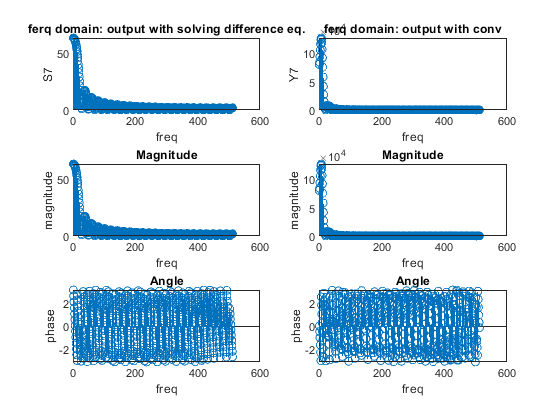

% with convolution
h7=filter(b7,a7,n);
y7=conv(x7,h7,'full');
%--
Y7=freqz(y7);
subplot(3,2,2)
stem(abs(Y7))
xlabel('freq'); ylabel('Y7'); title('ferq domain: output with conv');
subplot(3,2,4)
stem(abs(Y7))
xlabel('freq'); ylabel('magnitude'); title('Magnitude');
subplot(3,2,6)
stem(angle(Y7))
xlabel('freq'); ylabel('phase'); title('Angle');

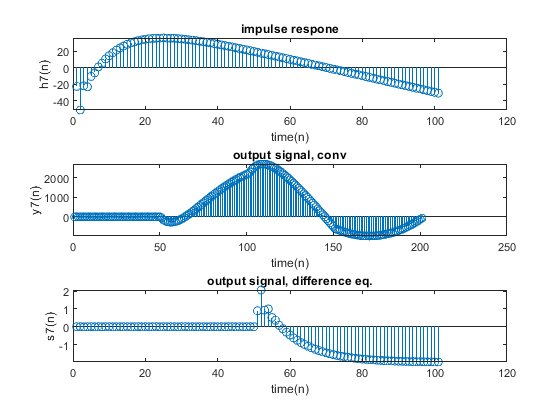

%--
figure(9)
subplot(3,1,1)
stem(h7)
xlabel('time(n)'); ylabel('h7(n)'); title('impulse respone');
subplot(3,1,2)
stem(y7)
xlabel('time(n)'); ylabel('y7(n)'); title('output signal, conv');
subplot(3,1,3)
stem(s7)
xlabel('time(n)'); ylabel('s7(n)'); title('output signal, difference eq.');